# Getting Started with MF-Tyre Library

## Quick Example

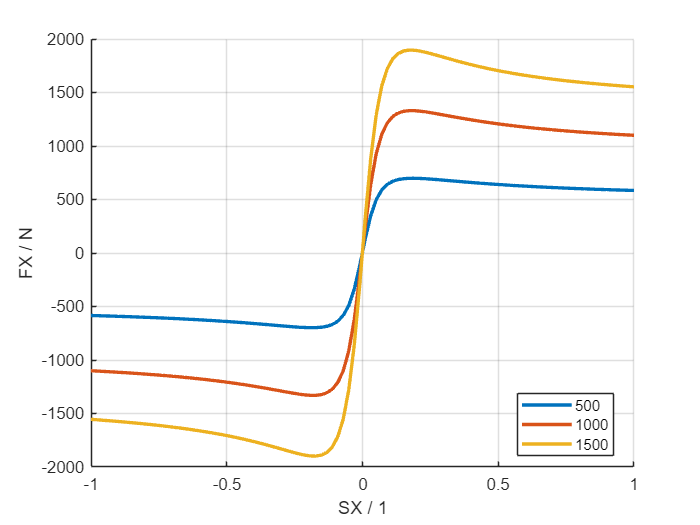

clear

folder = fileparts(matlab.desktop.editor.getActiveFilename());
file = fullfile(folder, 'examples/ttc/obfuscated.tir');
tyre = MagicFormulaTyre(file);

slipratio = linspace(-1, 1);
slipangle = 0;
figure(); grid on; hold on
for FZ = [500 1000 1500]
    FX = magicformula(tyre, slipratio, slipangle, FZ);
    plot(slipratio, FX, 'LineWidth', 2, 'DisplayName', num2str(FZ))
end
legend('Location', 'best'); xlabel('SX / 1'); ylabel('FX / N')

## More Examples

- [Full example fitting model to FSAE Tire Test Consortium data](matlab:open('Example_Fitter_FSAETTC'))

- [Plot model with data](matlab:open('Example_PlotWithData'))

- [Simulink example](matlab:open('Example_Simulink_MagicFormulaTyre'))

- [TYDEX file hanlding example](matlab:open('Example_TYDEX_FSAETTC'))

- [Compare this library with MFEVAL](matlab:open('Example_CompareToMFEVAL'))

## Documentation

Documentation is stored directly in the docstring of the functions and classes. Here is an overview of the packages:

help magicformula

 magicformula Unofficial implementation of Pacejka's magic formula.
    Orientation of inputs and outputs as defined per DIN ISO 8855:2011.
 
    [FX,FY,MZ,MY,MX] = magicformula(params,__)
    [FX,FY,MZ,MY,MX] = magicformula(file,__)
    [FX,FY,MZ,MY,MX] = magicformula(tyre,__)
 
    [...] = magicformula(__,SX,SA)
    [...] = magicformula(__,SX,SA,FZ)
    [...] = magicformula(__,SX,SA,FZ,IP)
    [...] = magicformula(__,SX,SA,FZ,IP,IA)
    [...] = magicformula(__,SX,SA,FZ,IP,IA,VX)
    [...] = magicformula(__,SX,SA,FZ,IP,IA,VX,side)
    [...] = magicformula(__,SX,SA,FZ,IP,IA,VX,side,version)
 
    For code-generation, all inputs have to be specified:
        [...] = magicformula(__,SX,SA,FZ,IP,IA,VX,side,version)
 
    Parameter input (mutually exclusive):
        - params:   provide as

help +magicformula

Contents of magicformula package:

                         FitMode - magicformula.FitMode is a class.
             InputArgumentParser - magicformula.INPUTARGUMENTPARSER Parses magic formula input arguments.
                       Parameter - magicformula.Parameter is a class.
           ParameterDescriptions - magicformula.ParameterDescriptions is a class.
               

help +tydex

Contents of tydex package:

ConstantParameter - tydex.ConstantParameter is a class.
    FileInterface - tydex.FileInterface is a class.
       FileReader - tydex.FILEREADER Reads tydex files into memory.
       FileWriter - tydex.FILEWRITER Writes tydex measurement objects to file.
MeasuredParameter - tydex.MeasuredParame

help tydex.Measurement

 Measurement TYDEX 1.3 formatted Measurement (Tyre Data Exchange Format)

    Documentation for tydex.Measurement

